# Week 7

*Author: Keith Chester*

*E-mail: kchester@wpi.edu*

## Introduction

For this week's assignment, we are exploring common cases of singularities for 6 axis robot arms. To this end, we will be analysing the Mecademic 6 axis robot arm and utilizing its specifications to simulate and demonstrate singularities.

To this end, we will be performing the following:

- Construct the DH table fo the Mecademic 6 axis arm.

- Demonstrate the construction of the Jacobian for the arm.

- Decouple the Jacobian for $J_p$ and $J_O$.

- Demonstrate the Mecademic's wrist singularity.

- Demonstrate the Mecademic's elbow singularity.

- Demonstrate the Mecademic's overhead singularity.

To do this we will utilize that the $\textrm{det}\left(J\right)=0$ when a singularity is occuring. We will simulate the Mecademic arm and its motions, recording angles and resulting end effector trajectory, to isolate and demonstrate where singularities occur during arm movement.

## Methods

The robot arm that we'll be working with is the Mecademic 500 6 axis arm.

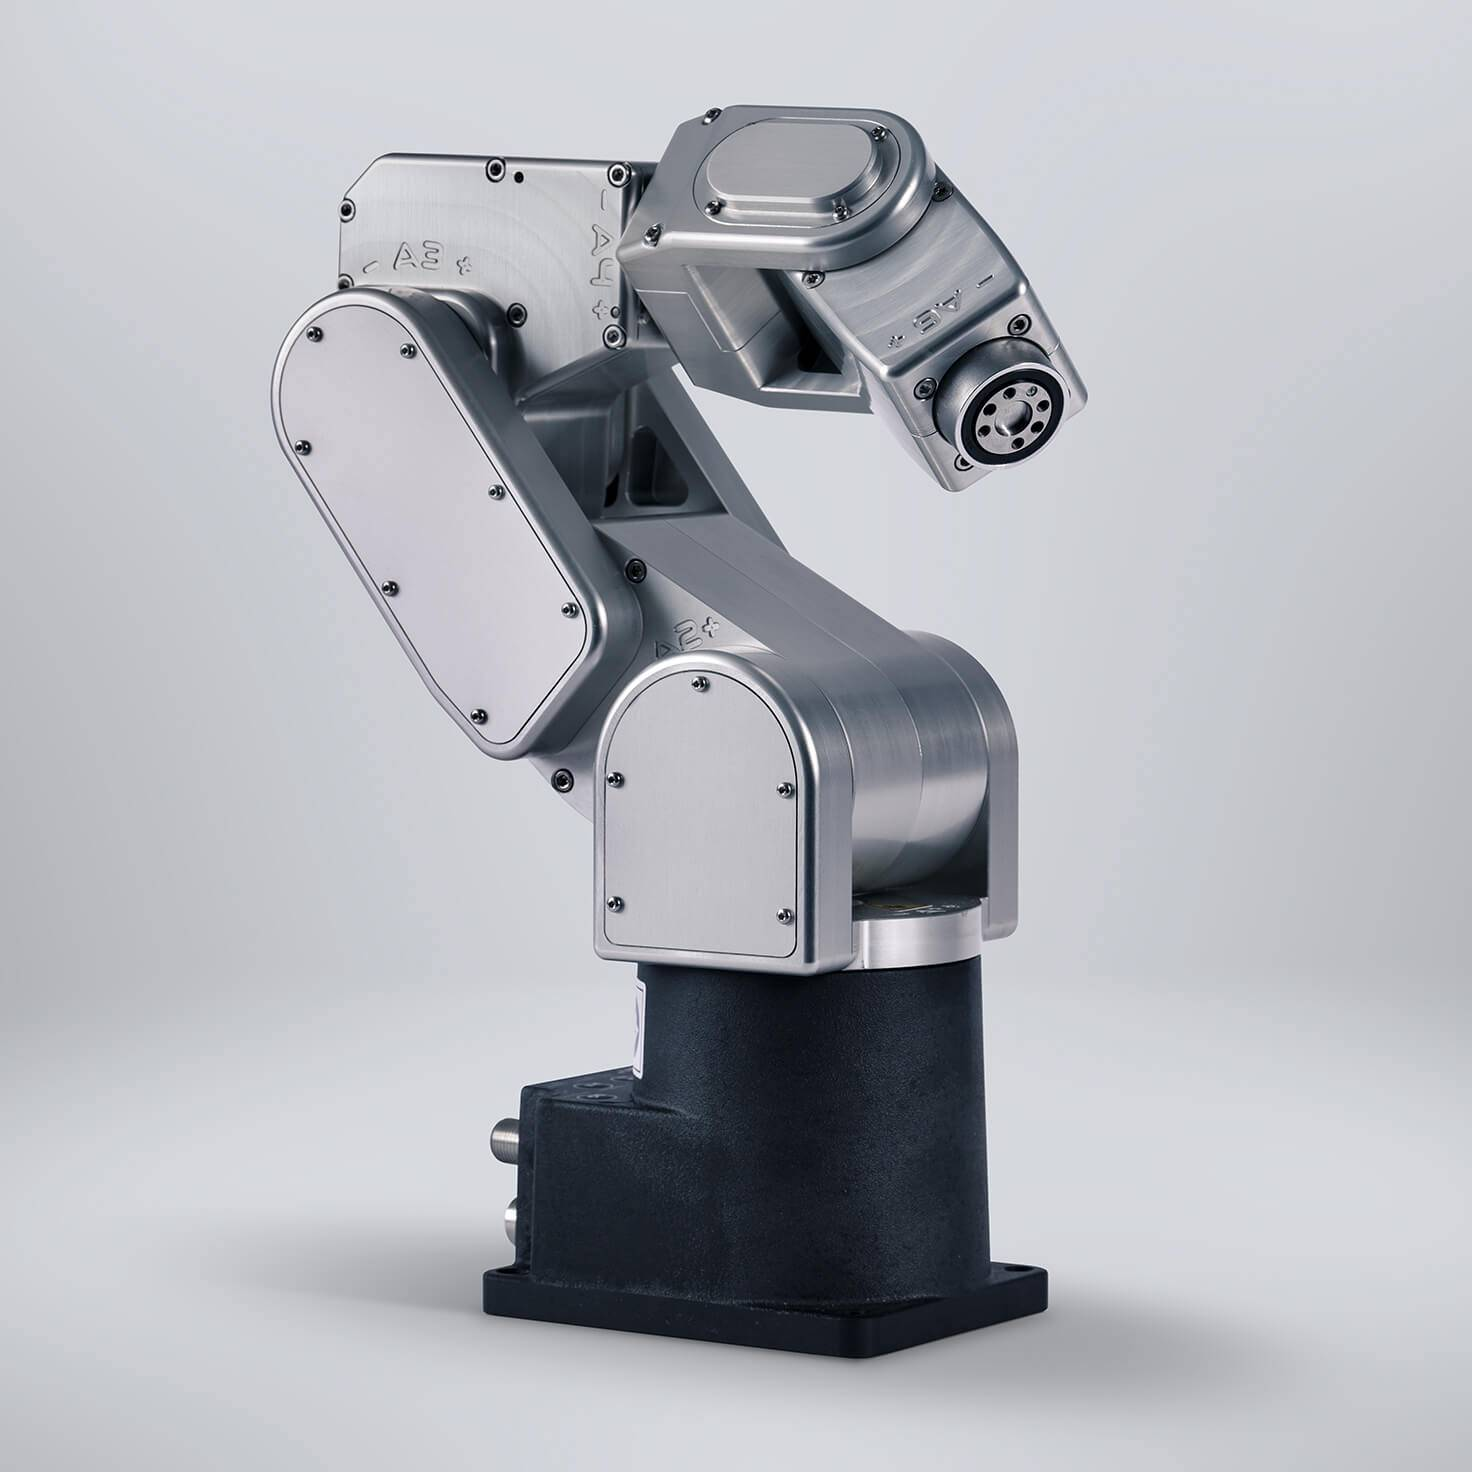

*Figure 1: The Mecademic 6 axis robot arm*

For the Mecademic arm, we first look at the technical specifications and assign coordinate frames for its joints through the DH convention.

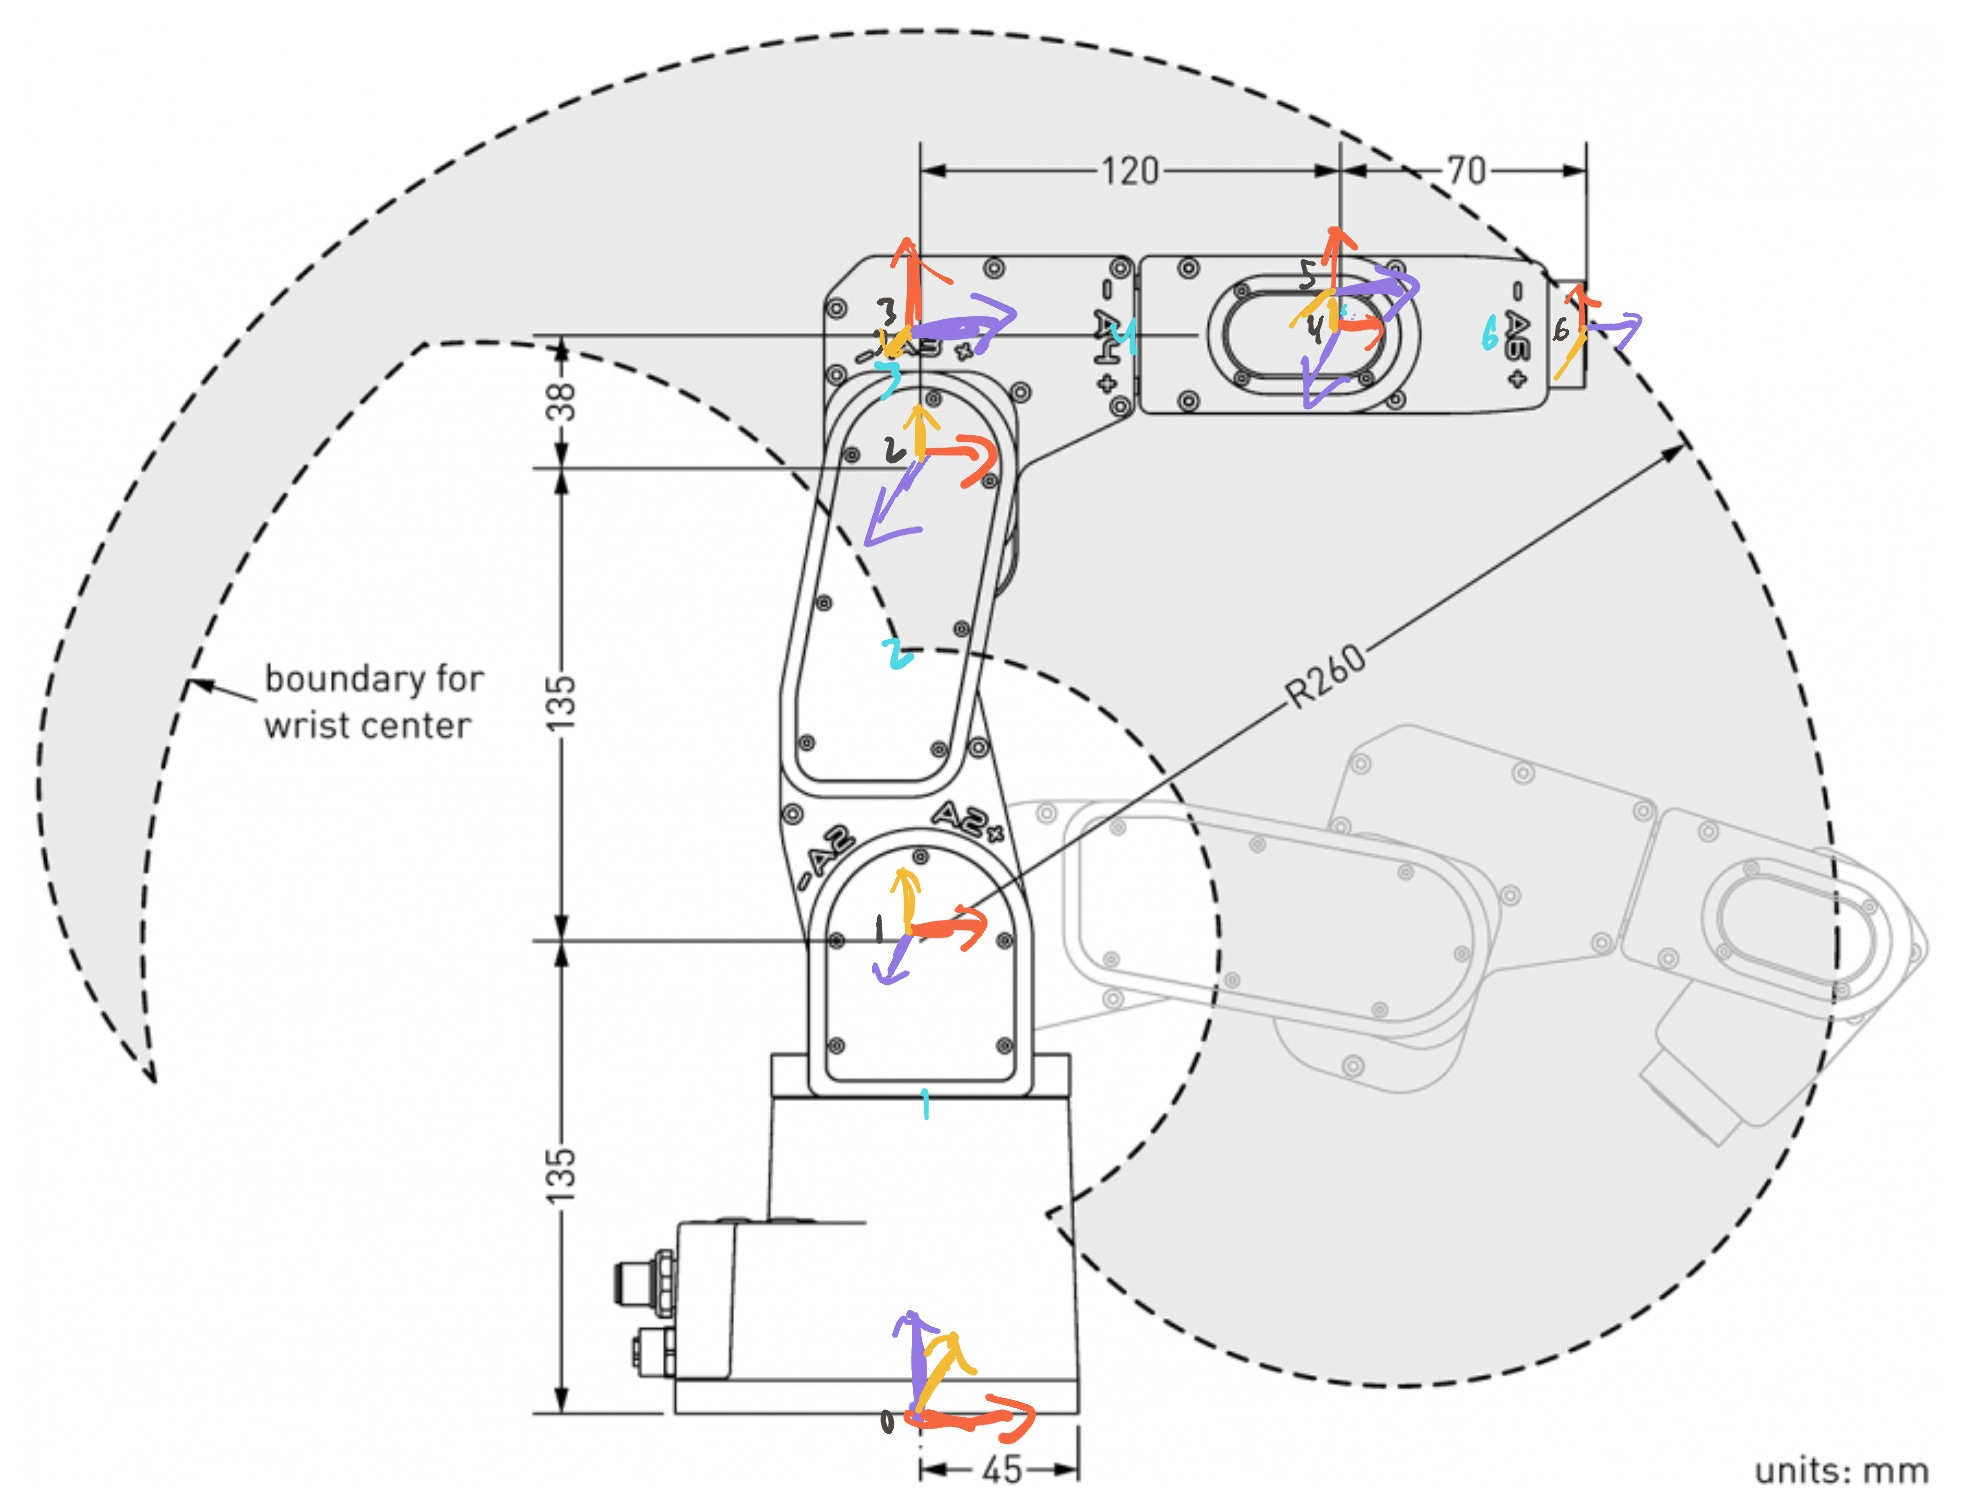

*Figure 2 The Mecademic 6 axis robot arm technical drawing overlayed with frames dervied through DH convention*

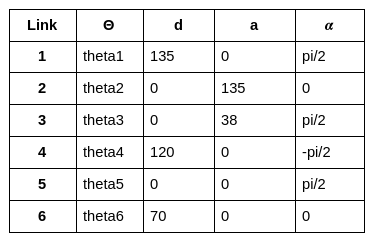

Figure 3: DH Table derived from the Mecademic arm frames above

First, we're going to derive the Jacobian for the DH table that we've generated. From here, we can decouple the Jacobian into $J_p$ and $J_O$, which are the Jacobian for the shoulder and elbow of the robot arm, and then the Jacobian for the wrist joints, respectively. This decoupling allows for easier calculation of a singularity as the determinant is easierfor a 3x3 matrix. When we do the actual calculations we will make use of the full determinant as computation power is not lacking. The equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccccc}
z_0 x\left(o_6 -o_0 \right) & z_1 x\left(o_6 -o_1 \right) & z_2 x\left(o_6 -o_2 \right) & z_3 x\left(o_6 -o_3 \right) & z_4 x\left(o_6 -o_4 \right) & z_5 x\left(o_6 -o_5 \right)\\
z_0  & z_1  & z_2  & z_3  & z_4  & z_5 
\end{array}\right\rbrack$$


*Equation 1: The Jacobian for our six axis arm*


$$\begin{array}{l}
J=\left\lbrack \frac{J_{11} \;\left|\;J_{12} \right.}{J_{21} \;\left|\;J_{22} \right.}\right\rbrack \\
J_P =\left\lbrack \frac{J_{11} }{J_{21} }\right\rbrack \\
J_O =\left\lbrack \frac{J_{12} }{J_{22} }\right\rbrack 
\end{array}$$


*Equation 2: The decoupled Jacobian*

When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. We will be making use of the $\textrm{det}\left(J\right)=0$ to prove that we have found a singularity throughout this paper.

Once we have explored the Jacobian symbollically, we will use numerical computation methods to explore the singularities for the Mecademic arm. Most six axis robot arms have three common sources of singularities which the Mecademic arm shares. A **wrist singularity**, an **elbow singularity**, and an **overhead** **singularity** when the tool path crosses above the arm's head.

The **wrist singularity** occurs when a wrist joint has its base frame and secondary frame - in our case $\theta_3$ and $\theta_5$ are co-linear - when $\theta_5 ==0\;\textrm{or}\;\theta_5 ==\pi$.

The **elbow singularity** occurs when the elbow's orientation matches a value based on the geometry of the robot - specifically when the angle of the elbow matches the arctan of the elbow's distance between $\theta_3$ and $\theta_4$. Specifically, $\theta_3 =-\arctan \left(\frac{120}{38}\right)=-\arctan \left(\frac{60}{19}\right)\approx -72\ldotp 48\;\textrm{degrees}$.

The **overhead singularity** occurs when the robot arm moves the end effector over the z-axis plane, as through the $\theta_0$ and $\theta_1$ z-axis. If the tool passes overhead, effectively when $x==y==0$ for a given *x, y, z* for the coordinates of the tool, a singularity occurs.

## Results

To start, let's use symbolics to generate our above DH table and then use our Jacobian functions - **jacobian_from_dh_table**, to generate our Jacobian from this DH table.

syms theta1 theta2 theta3 theta4 theta5 theta6
dh_table = {  %theta        %d          %a      %alpha
            [   theta1       135          0       pi/2    ],
            [   theta2       0            135     0       ],
            [   theta3       0            38      pi/2    ],
            [   theta4       120          0       -pi/2   ],
            [   theta5       0            0       pi/2    ],
            [   theta6       70           0       0       ],
           };

Now we'll build the Jacobian from this DH table - we'll be utilizing the following equation for our 6 axis arm:


$$J=\left\lbrack \begin{array}{cccccc}
z_0 x\left(o_6 -o_0 \right) & z_1 x\left(o_6 -o_1 \right) & z_2 x\left(o_6 -o_2 \right) & z_3 x\left(o_6 -o_3 \right) & z_4 x\left(o_6 -o_4 \right) & z_5 x\left(o_6 -o_5 \right)\\
z_0  & z_1  & z_2  & z_3  & z_4  & z_5 
\end{array}\right\rbrack$$


*Equation 1: The Jacobian for our six axis arm*

The below Jacobian is going to be quite extensive given the complexity of the arm.

J = jacobian_from_dh_table(dh_table, true)

We can debouple the Jacobian by breaking the large matrix into small subsections, creating $J_p$ and $J_O$, which accounts for the first half of the arm and the wrist.

J11 = J(1:3,1:3)

J12 = J(1:3, 4:6)

$$J12 = \left(\begin{array}{ccc} 70\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\right) & 70\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-70\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right)+70\,\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right) & 0\\ -70\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)\right) & 70\,\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)-70\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)-70\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{5}\right) & 0\\ -70\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & 70\,\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{5}\right)+70\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right) & 0 \end{array}\right)$$

J21 = J(4:6, 1:3)

$$J21 = \left(\begin{array}{ccc} 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 \end{array}\right)$$

J22 = J(4:6,4:6)

$$J22 = \left(\begin{array}{ccc} \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right) & \sin\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)\right)+\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{5}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\right)\\ -\cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{4}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)-\cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{5}\right) \end{array}\right)$$

Here we see the decoupled $J_p$ and $J_O$ from the above sections:

J_0 = J(1:6,4:6)

J_P = J(1:6, 1:3)

### Wrist Singularity

The wrist singularity occurs when $\theta_5 ==0$. We know a singularity occurs if $\textrm{det}\left(J_O \right)==0$. As such, we are going to set each joint in the arm to some value and then iterate over the total range of motion that $\theta_5$ can move over. The values that can be assigned to each $\theta_i$ is based upon the below technical specification joint limits for each joint.

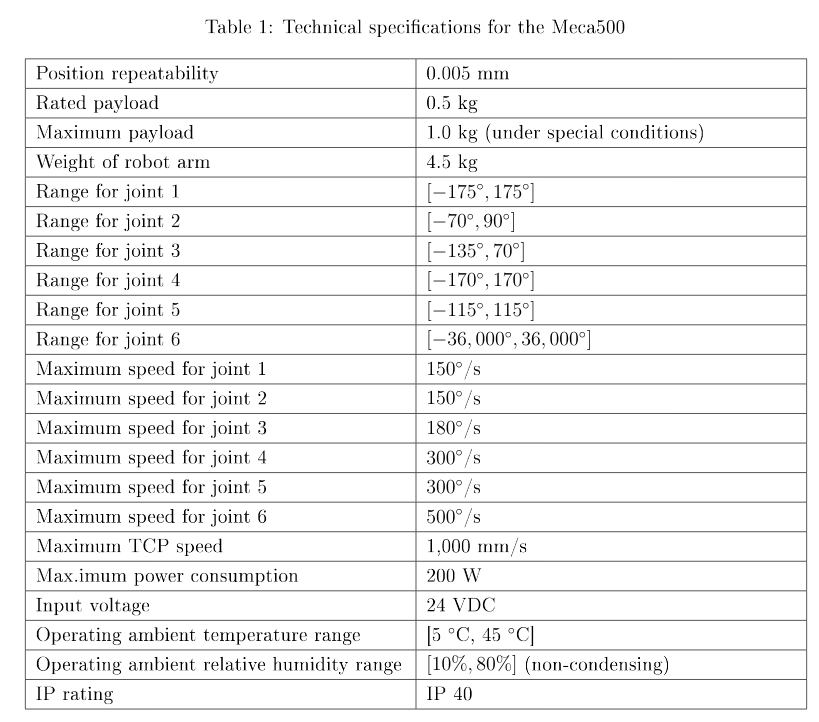

*Figure 4: The technical specifications for the Mecademic Arm - specifically its joint angle limits are being referred to here*

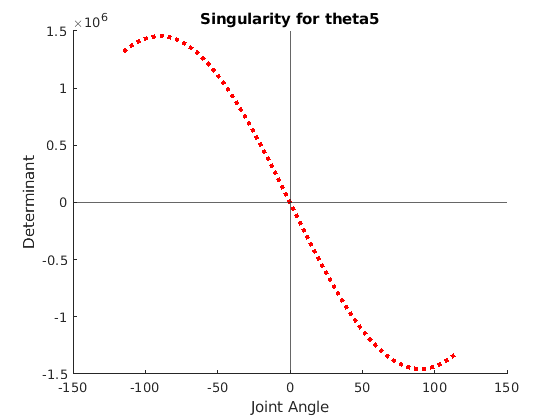

theta1 = 45;
theta2 = -30;
theta3 = 0;
theta4 = 100;
theta6 = 0;

determinants = zeros(2, 230);
theta5s = -115:115;

for step = 1:230
    dh_table = {  %theta      %d          %a      %alpha
            [   theta1        135          0       90    ],
            [   theta2        0            135     0     ],
            [   theta3        0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5s(step) 0            0       90    ],
            [   theta6        70           0       0     ],
           };
    J = jacobian_from_dh_table(dh_table);
    
    determinants(1, step) = theta5s(step);
    determinants(2, step) = det(J);
    
end

figure
title("Singularity for theta5")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;

plot(determinants(1,:), determinants(2, :), 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
xline(0);
yline(0);
hold off;

*Figure 5: The determinant of the Jacobian mapped against a changing *$\theta_5$

As we can see from the above graph, the determinant of the Jacobian goes to 0 when $\theta_5 ==0$. This is as expected.

### Elbow Singularity

After the wrist singularity, we will look at the elbow singularity. We expect the singularity to occur when the elbow joint - $\theta_3$- hits a certain point. As per the question, we expect the singularity to occur when $\theta_3 =-\mathrm{arctan}\left(\frac{60}{19}\right)\approx -72\ldotp 48$ degrees. Let's go through the total joint range of angles for the given elbow joint and see if we can confirm the expected singularity. All set joints are set to the limits of the robot's limits as described above.

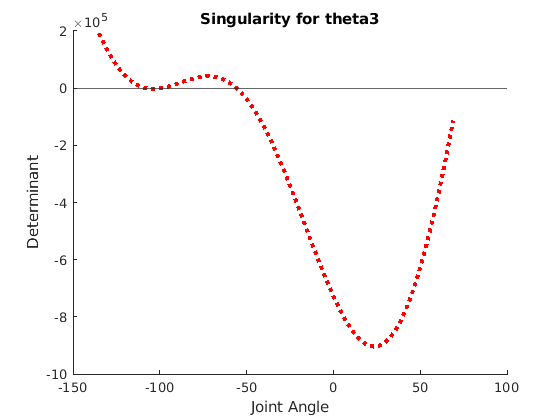

theta1 = 45;
theta2 = -30;
theta4 = 100;
theta5 = 30;
theta6 = 15;

determinants = zeros(2, 205);
theta3s = -135:70;

for step = 1:205
    dh_table = {  %theta      %d          %a      %alpha
            [   theta1        135          0       90    ],
            [   theta2        0            135     0     ],
            [   theta3s(step) 0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5        0            0       90    ],
            [   theta6        70           0       0     ],
           };
    J = jacobian_from_dh_table(dh_table);
    
    determinants(1, step) = theta3s(step);
    determinants(2, step) = det(J);
    
end

figure
title("Singularity for theta3")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;

plot(determinants(1,:), determinants(2, :), 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
yline(0);

hold off;

Here we see the singularity occuring at two locations - one at the -72.48 degrees expected and another likely from another combination of angles moving it past a key point.

Let's try a simulation and animation. We'll be moving the elbow joint only - the wrist joint is settable below. We'll only move a certain range for the elbow to try and get the elbow to move past its singularities.

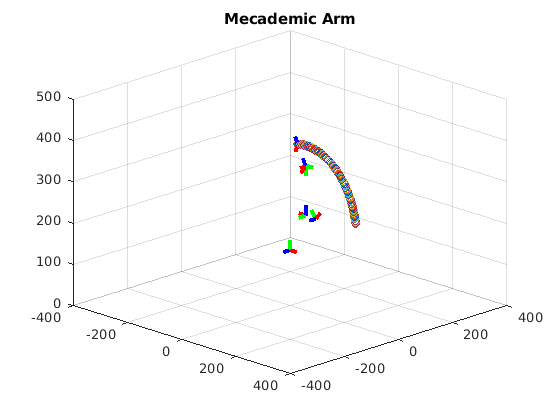

theta4 = 100;
theta5 = 30;
theta6 = 15;

thetas = linspace(45, 135, 100);

 

% Define our animation's figure settings
elbow_figure = figure;
title("Mecademic Arm")
grid on
hold on
axis([-400 400 -400 400 0 500])
view([45 25])
lines = [];
xyzs = zeros(3, length(thetas));
animation_length_seconds = 5;

% Perform our animation
for step = 1:length(thetas)
    % Assign our theta for each step
    theta = thetas(step);
    
    % For our theta values, create our DH Table for the arm in this
    % configuration
     dh_table = {  %theta      %d          %a      %alpha
            [   0             135          0       90    ],
            [   45            0            135     0     ],
            [   theta         0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5        0            0       90    ],
            [   theta6        70           0       0     ],
           };
        
    % Find our transforms from the D_H table
    transforms = transforms_from_dh_table(dh_table);
    
    % Clean up all existing lines from the previous animation step
    for index = 1:length(lines)
        delete(lines(index))
    end
    lines = [];
    
    % Draw coordinate axes
    lines = cat(2, lines, draw_axes_for_transforms(transforms, 25));
    
    % Draw the actuator endpoint and save the (X,Y,Z) for this moment
    actuator = transforms{6} * [0; 0; 0; 1;];
    plot3(actuator(1), actuator(2), actuator(3), 'o')
    xyzs(1, step) = actuator(1);
    xyzs(2, step) = actuator(2);
    xyzs(3, step) = actuator(3);
    
    % Pause for the appropriate length of time to get our animation to 5
    % seconds
    drawnow
    pause(animation_length_seconds/length(thetas))

end

hold off;

With the simulation ran, we have a set of variables now in memory that we can iterate over to calculate our Jacobian for each set of joint angles, and try and determine if we moved past a singularity.

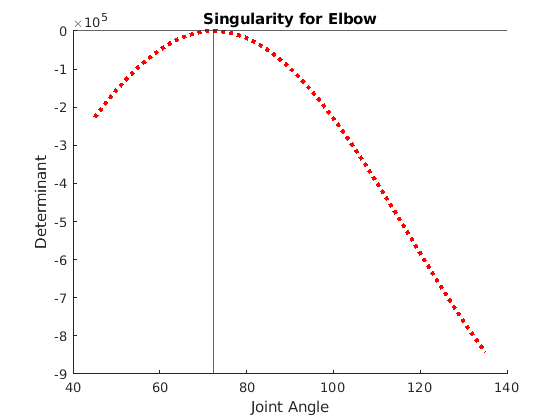

distances = zeros(1, length(thetas));
determinants = zeros(1, length(thetas));
for step = 1:length(thetas)
    theta = thetas(step);
    dh_table = {  %theta      %d          %a      %alpha
            [   0             135          0       90    ],
            [   90            0            135     0     ],
            [   theta         0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5        0            0       90    ],
            [   theta6        70           0       0     ],
           };
    determinants(step) = det(jacobian_from_dh_table(dh_table));
end

figure
title("Singularity for Elbow")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;
plot(thetas, determinants, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
yline(0);
xline(72.43);
hold off;

Here we see a clearer isolation of the singularity - at -72.48 degrees the determinant hits 0 - thus signifying a singularity.

### Shoulder Singularity

The shoulder joint can create a singularitiy when it moves the end effector through a trajectory that moves past the z-axis plane directly above the robot, through axis 1 and 2. To this end, we will be moving the shoulder joint ($\theta_2$) to try and tool over its head.

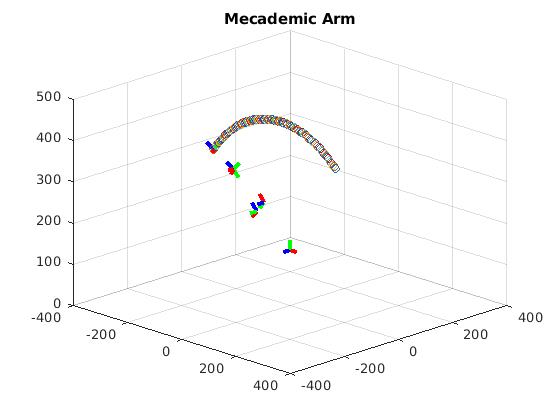

theta4 = 100;
theta5 = 30;
theta6 = 15;

thetas = linspace(45, 135, 100);

 

% Define our animation's figure settings
shoulder_figure = figure;
title("Mecademic Arm")
grid on
hold on
axis([-400 400 -400 400 0 500])
view([45 25])
lines = [];
xyzs = zeros(3, length(thetas));
animation_length_seconds = 5;

% Perform our animation
for step = 1:length(thetas)
    % Assign our theta for each step
    theta = thetas(step);
    
    % For our theta values, create our DH Table for the arm in this
    % configuration
     dh_table = {  %theta      %d          %a      %alpha
            [   0             135          0       90    ],
            [   theta         0            135     0     ],
            [   90            0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5        0            0       90    ],
            [   theta6        70           0       0     ],
           };
        
    % Find our transforms from the D_H table
    transforms = transforms_from_dh_table(dh_table);
    
    % Clean up all existing lines from the previous animation step
    for index = 1:length(lines)
        delete(lines(index))
    end
    lines = [];
    
    % Draw coordinate axes
    lines = cat(2, lines, draw_axes_for_transforms(transforms, 25));
    
    % Draw the actuator endpoint and save the (X,Y,Z) for this moment
    actuator = transforms{6} * [0; 0; 0; 1;];
    plot3(actuator(1), actuator(2), actuator(3), 'o')
    xyzs(1, step) = actuator(1);
    xyzs(2, step) = actuator(2);
    xyzs(3, step) = actuator(3);
    
    % Pause for the appropriate length of time to get our animation to 5
    % seconds
    drawnow
    pause(animation_length_seconds/length(thetas))

end

hold off;

The following section can be executed separately (to avoid the long animation time) to generate plots from data recorded during the above simulation. We'll be mapping known joint angles against the calculated jacobian and its' determinant, as well as the joint nagles vs the X/Y distance from the shoulder's Z-axis.

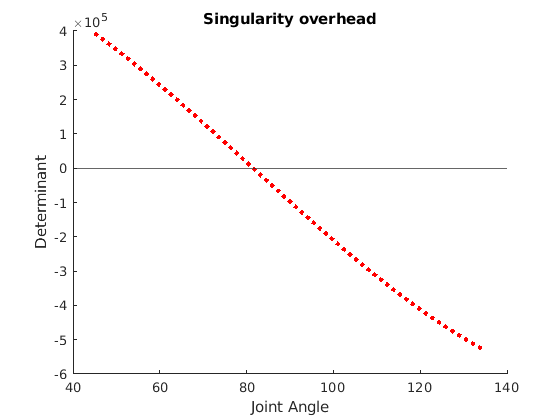

distances = zeros(1, length(thetas));
determinants = zeros(1, length(thetas));
for step = 1:length(thetas)
    theta = thetas(step);
    distances(step) = sqrt(xyzs(1, step)^2 + xyzs(2, step)^2);
    dh_table = {  %theta      %d          %a      %alpha
            [   0             135          0       90    ],
            [   theta         0            135     0     ],
            [   90            0            38      90    ],
            [   theta4        120          0       -90   ],
            [   theta5        0            0       90    ],
            [   theta6        70           0       0     ],
           };
    determinants(step) = det(jacobian_from_dh_table(dh_table));
end

figure
title("Singularity overhead")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;
plot(thetas, determinants, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
yline(0);
hold off;

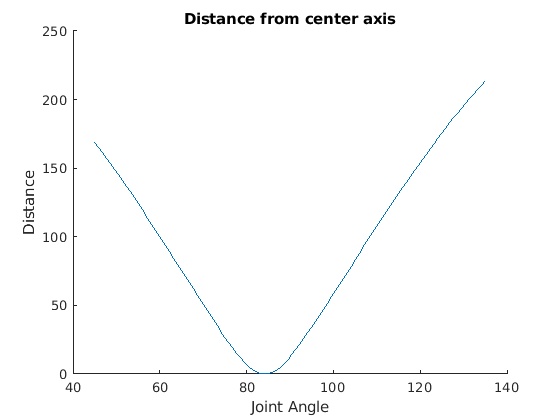

figure
hold on;
plot(thetas, distances-min(distances));
title("Distance from center axis")
xlabel('Joint Angle')
ylabel('Distance')
hold off;

The first chart that we are creating will map the calculation of the determinant against the joint angle of $\theta_2$.  The second chart that we are creating maps the total distance of the X/Y position of the end-effector, where $\textrm{distance}=\sqrt{x^2 +y^2 }$, vs the joint angle. We can see the output of this work below:

*Figure 6: The determinant of the Jacobian vs its joint angle*

*Figure 7: The X/Y distance from the shoulder Z-axis by joint angle*

As the distance of the end-effector from the overhead axis closed to 0, we approached and surpassed a singularity. This demonstrates that a singularity does exist above the robot.

### Functions

Below are a collection of functions utilized to make the above code easier, repeatble, and more manageable.

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

### draw_axes_for_transforms

Given a cell of transforms, draw each of them to a given size in the current active plot. It does this by calling **draw_coordinate_axis** above.

function lines = draw_axes_for_transforms(transforms, line_size)
    lines = [];
    for index = 1:length(transforms)
        [x_line, y_line, z_line] = draw_coordinate_axis(transforms{index}, line_size, 'red', 'green', 'blue');
        lines(end+1) = x_line;
        lines(end+1) = y_line;
        lines(end+1) = z_line;
    end
end

## Discussion

In this paper, we explored the Mecademic six axis robot arm and used it to analyze common singularities for six axis robot arms.

First, we looked at the Jacobian and demonstrated decoupling the Jacobian to make determinant calculation easier (3x3 matricies vs a singular 6x6 matrix). We then sought numerical analysis to demonstrate singularities at several points.

For the wrist singularity, we demonstrated that at $\theta_5 ==0$, the determinant of the Jacobian of the arm goes to 0. For the elbow singularity, we demonstrated through a set of joint angles and through arm simulation that moving the arm past a point in which its geometry forms a relationship where inverse kinematics is unsolvable - for our arm, -72.48 degrees. Finally, we demonstrated the overhead singularity the base joints of the arm can create when we pass the end effector of the robot arm through the overhead of the arm, above the plane created by the base plane's z-axis. Our simulation here moved the tool over the robot head and demonstrates a clear singularity when, for a given *x, y, z* of the tool effector's position, $x==y==0$.